# 6. Transistor current gain ($\beta$ or $h_{fe}$)

© B. Rasnow 31may25

## Objective 

Measure the current gain, $h_{fe} = \beta$ characteristic of an NPN transistor.

## Background

We saw how the voltage and current of a 2-terminal electronic device are not independent. Their relationships are defining characteristics of the device. Resistors have linear voltage-current relationships, LEDs are closer to "hockysticks", for V < $V_f$ $i$ ~ 0, and above $V_f$ the current increases somewhat exponentially. Bipolar junction transistors (BJT) have 3 terminals that typically form 2 circuits with a shared emitter. The 3 common regimes of a BJT are shown in Fig. 1. In this lab, we'll use the Arduino to measure base and collector currents and compute their ratio. In the "active regime", this ratio is a constant called Hfe = $\beta = I_C/I_B$. 

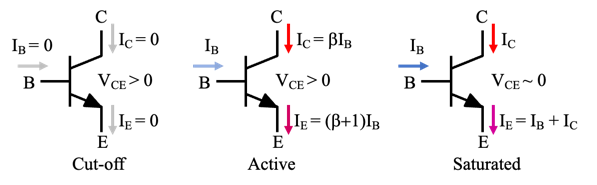

       Figure 1. Three common states of a NPN BJT. 

The value of $\beta$ is a characteristic of the transistor, and relatively independent of the circuit. Many factors affect $\beta$, including intrinsic geometry, doping and structural composition, and temperature. Unlike resistors, who's values are specified within a narrow range, e.g., R is within 1% or 5% of its rated value, the range of $\beta$ is often wide, e.g., 40-400. When using transistors, robust designs don't rely on a particular value but incorporate [negative feedback](https://en.wikipedia.org/wiki/Negative_feedback) or other mechanisms to make the circuit's behaviors constant for any $\beta$ greater than a minimum value. Some DMMs can measure $\beta$ directly, more reliable measurements are from dedicated testors like [https://peak.retronics-uk.com/product/dca55/,](https://peak.retronics-uk.com/product/dca55/,) and back in the early days of electronics we used "curve tracer" machines, e.g., [https://en.wikipedia.org/wiki/Semiconductor_curve_tracer.](https://en.wikipedia.org/wiki/Semiconductor_curve_tracer.) Today we'll measure $\beta$ with our LM317 power supply, Arduino, and MATLAB. 

This document doesn't attempt to explain transistor theory, you'll have to look elsewhere for that. E.g., I found this explanation websurfing and it  "clicked" or resonated with me. But maybe that's because I had previously read a dozen other explanations that didn't make as much sense, but left me more receptive to this one ... 

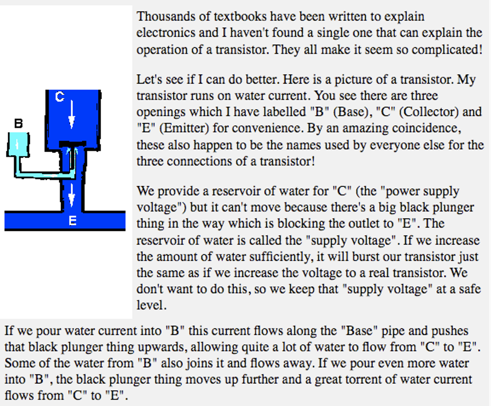

I like the analogy for a BJT, although of course the "black plunger thing" can more accurately be described with (more complicated) motionless solid state physics. Key phenomenology is that a little base-to-emitter current controls a much larger collector-emitter current and $\beta$ characterizes that current gain. We'll make a test circuit with two resistors Rb in series with the base and Rc in series with the collector, which serve to both limit and transduce the base and collector currents into easily measurable voltages (i = $\Delta$V/R) according to Ohm's Law (Fig. 2). 

## Methods 

### Hardware Interface

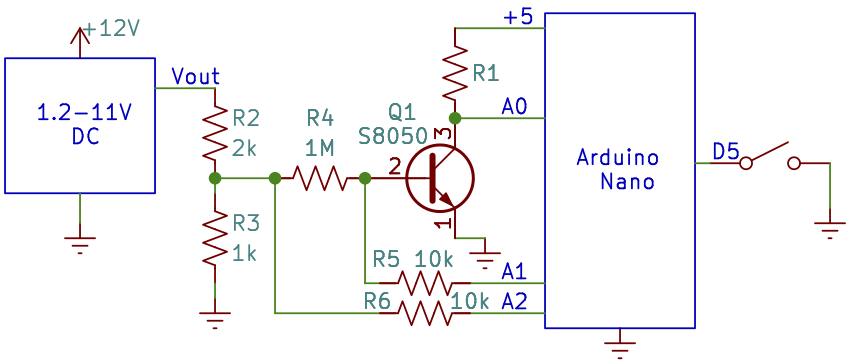 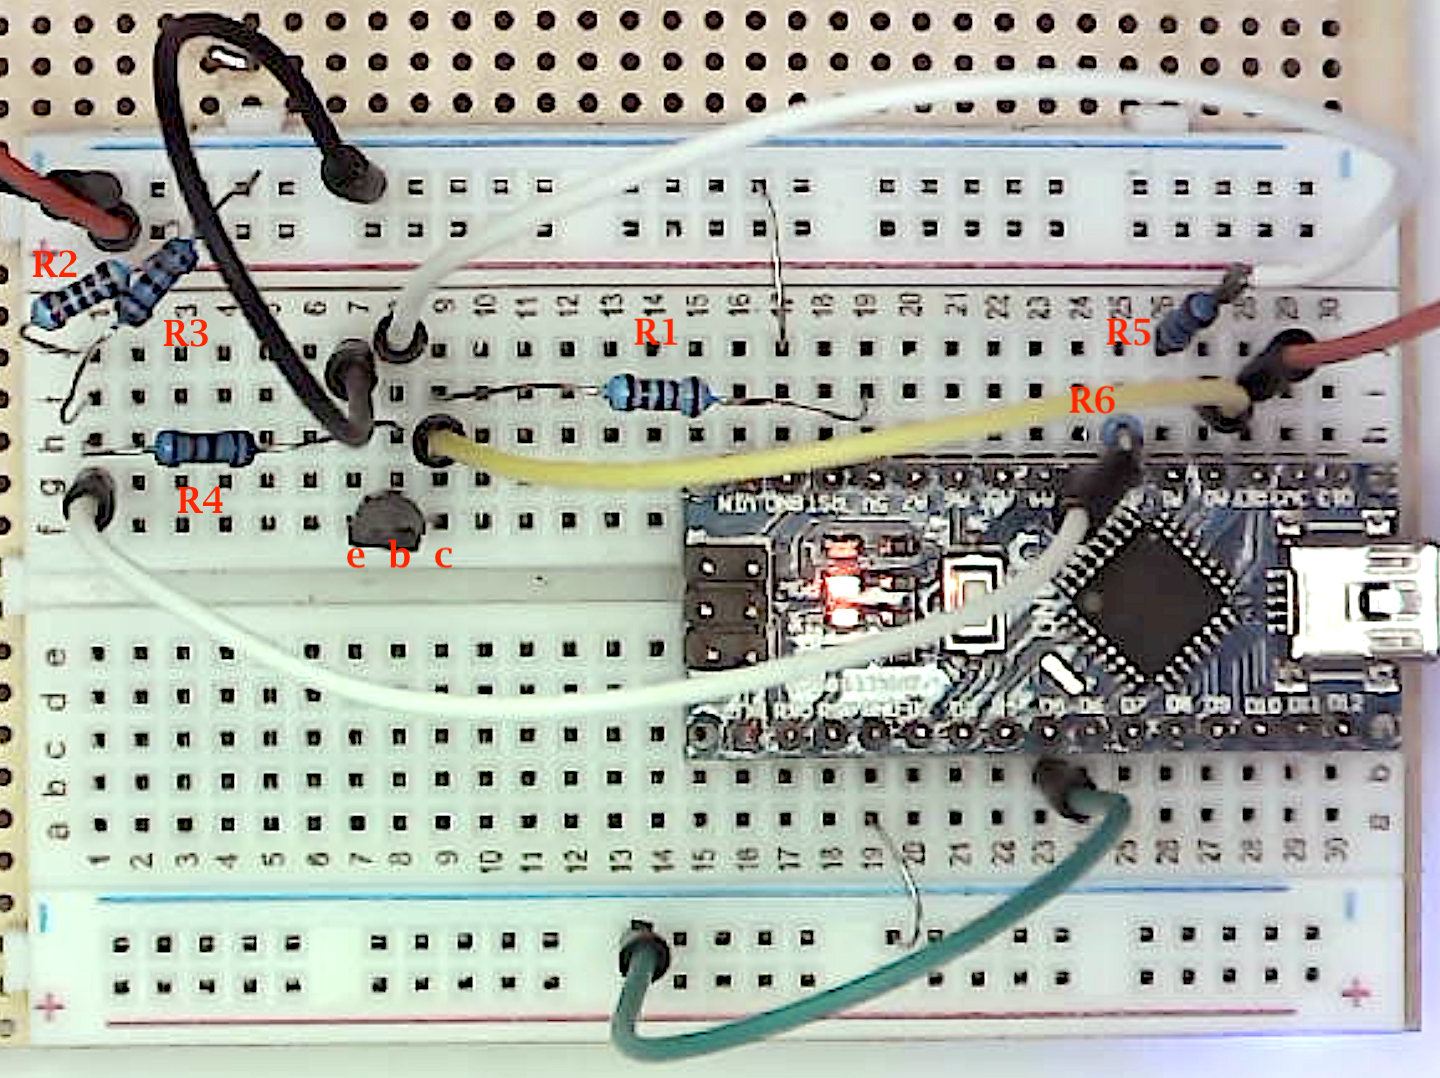

    Figure 2. Schematic and breadboard of the $\beta$ measuring circuit. 

- R2 and R3 are voltage dividers reducing the LM317's output by ~1/3. Dividing LM317's voltage by 3 ensures Arduino isn't damaged measuring V>5V, but it also allows measuring transistor behavior as it becomes active ~0.5V, below the LM317's minimum output ~1.25V.

- R5 and R6 provide current limiting protection to the Arduino in case the voltage divider fails, a wire shorts, etc. Analog inputs are high impedance and draw little current (normally) so R5-6 have (normally) no effect on measurements.

- R4 = Rb turns the varying LM317 voltage (divided by ~3) into a varying current into the base of Q1. Base current from Ohm's Law is ib = (A2-A1) / R4. The high value of R4 $=1M\Omega$ lets us explore the transistor's behavior for small ib, before it saturates.

- R1 = Rc both limits and enables measurement of the resulting collector current as a voltage, ic = (vref-A0) / R1. Reducing R1 < ~500$\Omega$ risks burning out the Arduino, which provides current through R1 up to ~5V/R1 when the transistor is saturated. I have destroyed Arduinos from sinking >10mA for long durations. Repeat measurements with a few values of R1, e.g., 1k, 4.7k, 10k, 20k. 

- Transistor Q1 is an S8050 or 2N2222 [1]. You also may have S8550 (PNP) transistors in your kit -- they won't work in this circuit. Carefully read the part number and look up a datasheet for it's pinout. (A trick that usually works is set your DVM to Diode Test mode and measure all permutations of the pins. You'll get two similar diode $V_f$ readings ~ 0.6V. The common terminal is the base, if it's the positive DMM lead then the transistor is NPN (the base is the 'P'). Typically $V_{BC} < V_{BE}$ although the difference maybe small. 

- Measure resistor values with your DMM ohmmeter before connecting them in the circuit. Use clip leads to connect the resistors to your DMM. Try holding the 1M$\Omega$ against the DMM leads with your two hands, and you'll probably measure a value considerably less than 1M, because your body's finite resistance is in parallel with the 1M DUT. Shorting the clip leads measures the loop resistance of the leads, which if not zero can be subtracted from other measurements for a more precise result. 

- Measure `vref`, Arduino's reference voltage on pin 3, using jumper wires and clip leads to avoid shorting adjacent pins.

### Software Interface

Same Arduino code as prior experiments, except we need to measure a 3rd voltage (generally we'd need to measure 2 voltages on either side of each resistor, but one side of Rc is at Vref which we'll measure once with the DVM, and = 1023ADU always). When D5 is grounded, data is printed to the Serial Monitor ~5 times per second. Ground D5, then slowly vary the LM317 voltage, unground D5, and copy the Serial Monitor data into MATLAB.

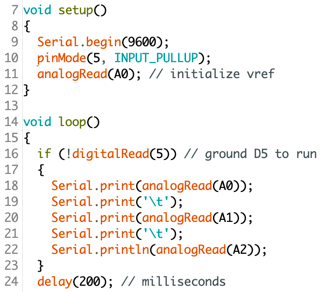

        Figure 3. Arduino source code measures and prints 3 voltages approximately 5 times per second. Note the last print statement calls a different print function that terminates the line).

### Data Interface

Copy data from the Serial Monitor and paste into MATLAB variable `data`. A first look at the raw data is often useful. E.g.,

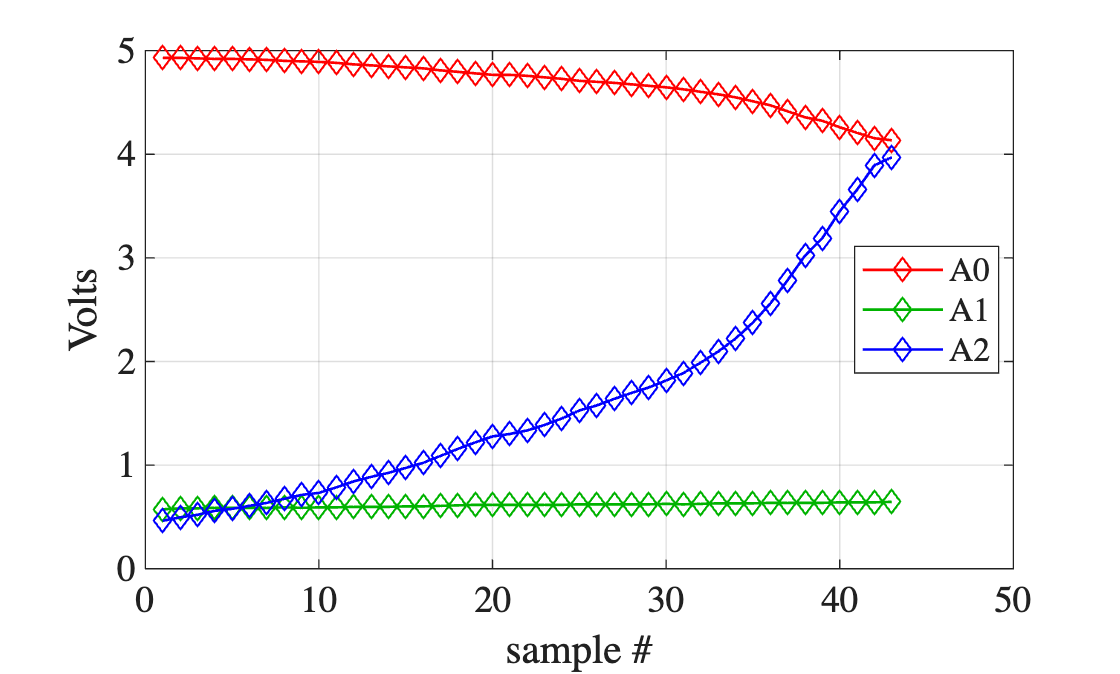

vref = 4.93; % volts on aref pin
adu2volts = vref / 1023;
R2 = 1990; % ohms
R3 = 999; % ohms

Rb = 1.014e6; % ohms, measured with dmm
Rc = 1003; % R1, ohms, measured with dmm -- try a few other (larger) values
data = [ ... % A0, A1, A2
% paste your Serial Monitor Data below, trim duplicate rows at start & end
1023	119	96
1023	121	103
1022	121	108
1021	122	116
1021	122	120
1020	122	126
1019	122	132
1017	123	140
1016	122	148
1015	123	152
1013	123	163
1010	124	175
1008	124	184
1006	124	192
1004	125	202
1002	125	212
998	126	226
995	127	240
992	128	253
989	128	265
989	128	270
987	128	277
984	128	288
981	128	301
977	129	317
975	129	327
973	129	340
970	129	352
967	129	363
964	130	377
960	129	392
955	130	413
950	131	435
944	131	461
936	131	493
928	132	531
916	132	578
904	132	627
897	132	662
884	133	716
873	133	759
862	133	808
858	134	824
] * adu2volts;
plot(data,'d-'); 
xlabel('sample #'); ylabel('Volts');
legend('A0','A1','A2','location','best'); grid;

    Figure 4. Raw data from the Arduino.

Not a lot to quantify here because sample # is arbitrary. But if the curves aren't monotonic or reveal random noise, then troubleshoot and repeat. Vbe = A1 (green) hardly moves, acting like a forward biased diode with $V_f$ ~ 0.6V. Even though Vbe is nearly constant, ib is increasing, indicated by increasing A2 (blue). If the transistor is active, then the collector current should increase -- causing more voltage drop across Rc, V = icRc which causes Vce to drop according to KVL: Vref = Vce + icRc -- so if the 2nd term increases, the first one must proportionally decrease, and the red curve above does that. So far so good. To measure characteristics of the transistor (and not how smoothly one turns the LM317's pot), compute the key currents -- let's rename the columns first so the equations make more sense. I also changed the current units from amps to more convenient mA or $\mu$A. Draw the schematic in Fig. 2 and refer to it as you read the next block of code. 

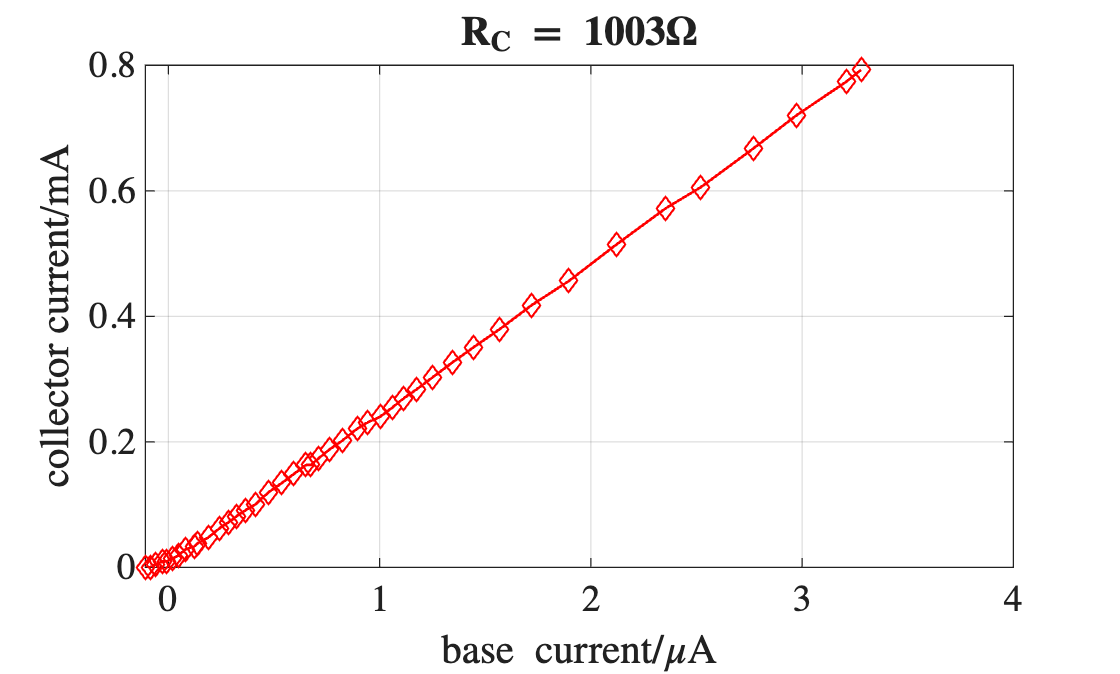

vce = data(:,1); % collector-emitter voltage
vbe = data(:,2); % base-emitter voltage
vin = data(:,3);
ib = (vin-vbe)/Rb * 1e6; % base current in microAmps (uA)
ic = (vref-vce)/Rc * 1e3; % collector current in mA
plot(ib, ic,'d-')
grid; xlabel('base current/\muA'); 
ylabel('collector current/mA')
title(sprintf('R_C = %.0f\\Omega', Rc)); % why \\?

        Figure 5. Collector vs. base currents.

Do a visual estimate of the slope before computing it with `polyfit.` $\Delta i_c / \Delta i_b = .55mA/2.8\mu A = 196$

We can tell MATLAB to exclude the lowest few points (where the transistor maybe not fully "active"), and perhaps the largest data where the transistor might be saturated, by creating a Boolean index variable that's true when e.g., ib > .1uA AND ic < 95% of its maximum value. Also since the slope has units of mA/uA, it has to be multiplied by 1000 uA/1mA = 1.

indx = ib > .1 & ic < .95 * max(ic);
p = polyfit(ib(indx), ic(indx), 1); 
fprintf('beta = %.1f\n', p(1)*1e3)

beta = 240.0


If it's not consistent with your visual estimate, troubleshoot why not. Rename `data` and `beta` and repeat with another value of R1 = Rc. 

Finally combine the multiple data sets into one graph. 

## Results

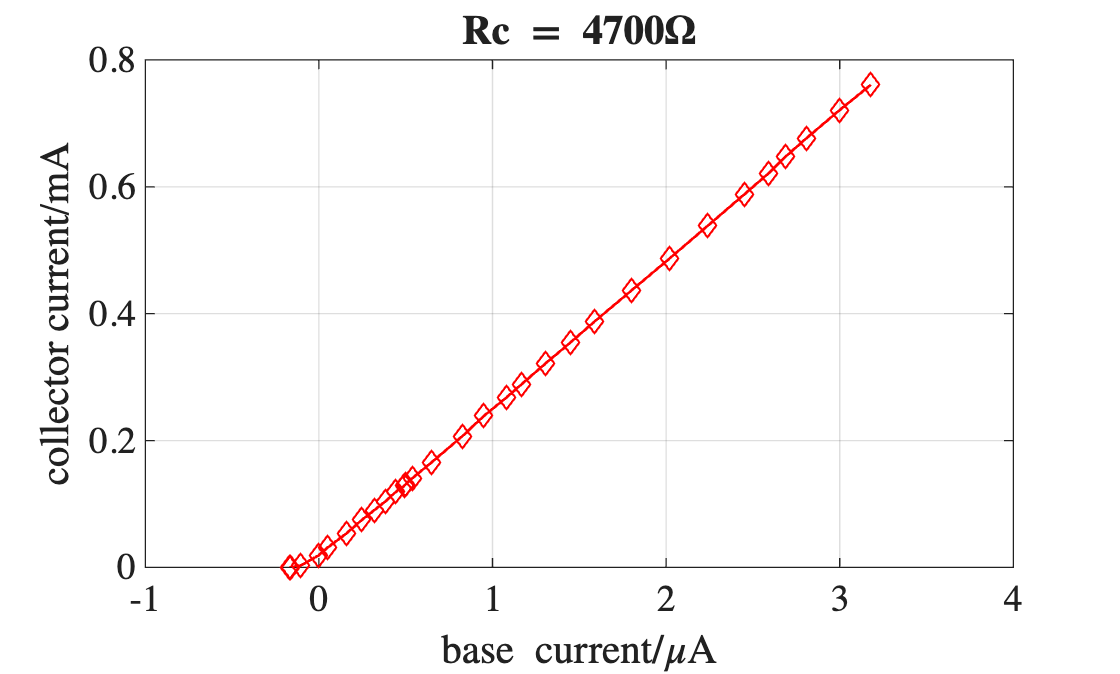

% save the prior data
ib1k = ib; ic1k = ic; beta(1) = p(1)*1e3;
Rc = 4700; % ohms measured with dvm
data = [...
1023	124	88
1023	124	89
1020	126	104
1005	126	125
993	128	138
971	128	161
950	128	180
935	129	196
921	128	209
907	128	221
897	128	232
895	128	233
886	128	241
861	128	265
821	128	302
790	129	329
762	129	356
742	129	374
709	129	404
677	129	434
645	129	463
597	129	508
548	129	554
498	129	600
449	129	645
417	130	675
391	129	695
363	130	721
320	130	761
281	130	799
] * vref / 1023; % now in volts
vce = data(:,1); % collector-emitter voltage
vbe = data(:,2); % base-emitter voltage
vin = data(:,3);
ib = (vin-vbe)/Rb * 1e6; % base current in uA
ic = (vref-vce)/Rc * 1000; % collector current in mA
plot(ib, ic,'d-')
grid; xlabel('base current/\muA'); 
ylabel('collector current/mA')
title(sprintf('Rc = %.0f\\Omega', Rc)); % why \\?

        Figure 6. Switching to $Rc = 4.7k \Omega$ appears to change nothing. 

Did I mess up? No, the data points have moved around, but the min and max appear the same, the beta is: 

indx = ib > .1 & ic < .95 * max(ic);
p = polyfit(ib(indx), ic(indx), 1); % help polyfit for more info
fprintf('beta = %g\n', p(1)*1e3)

beta = 234.815


Very consistent. This suggests that the collector resistor doesn't affect this curve -- the slope is indeed a *characteristic of the transistor*. What if we increase Rc ... such that say at ic ~0.5mA (around 1/2 the range above), ic*Rc ~ vref --> Rc = Vref / 0.5mA ~ 10kohm. 

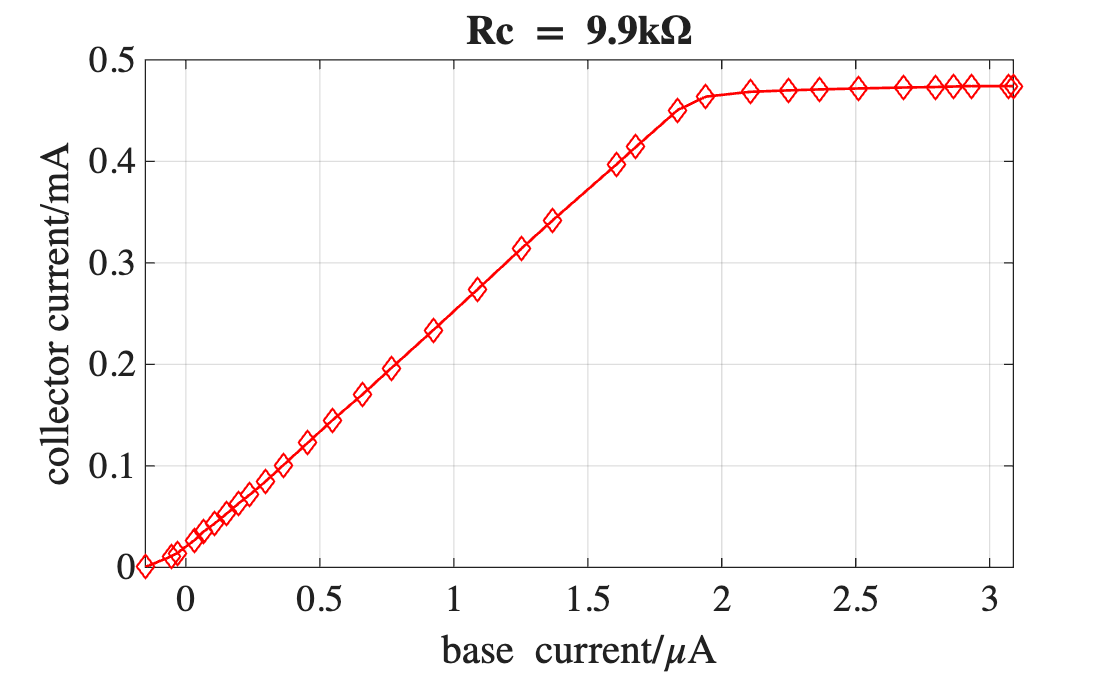

ib5k = ib; ic5k = ic; beta(2) = p(1)*1e3; % save the former results
vref = 4.76; % volts on aref pin -- the following measurements are on another day.

Rc = 9860; % new Rc, ohms measured with DMM
data = [...  % A0 A1 A2  
1022	123	90
1000	124	112
993	124	117
966	124	131
949	124	138
932	124	147
911	124	157
889	124	167
871	124	176
843	124	189
810	124	203
763	124	223
716	124	243
661	124	268
607	124	291
528	124	325
443	124	361
357	124	397
299	124	422
182	124	474
145	124	490
68	124	524
40	124	547
30	124	583
27	124	614
25	124	639
23	124	671
21	124	708
20	124	734
19	124	748
18	125	764
18	124	793
18	124	797
] * vref/1023; % volts
vce = data(:,1); % collector-emitter voltage
vbe = data(:,2); % base-emitter voltage
vin = data(:,3);
ib = (vin-vbe)/Rb * 1e6; % base current in uA
ic = (vref-vce)/Rc * 1000; % collector current in mA
plot(ib, ic,'d-')
grid; xlabel('base current/\muA'); 
ylabel('collector current/mA')
title(sprintf('Rc = %.1fk\\Omega', Rc/1000)); % why \\?

        Figure 7. Collector vs. base currents with $Rc = 10k \Omega$, which causes the BJT to saturate around $i_C = .43mA$.

indx = ib > .1 & ic < .95 * max(ic);
p = polyfit(ib(indx), ic(indx), 1); % help polyfit for more info
fprintf('beta = %.1f\n', p(1)*1e3)

beta = 237.5


The plateau value is saturation. The collector-emitter resistance approaches zero and ic ~ Vref / Rc = 

vref / Rc * 1000 % mA

ans = 0.4828

Compare to the graph:

max(ic) 

ans = 0.4743

One more resistor value: 

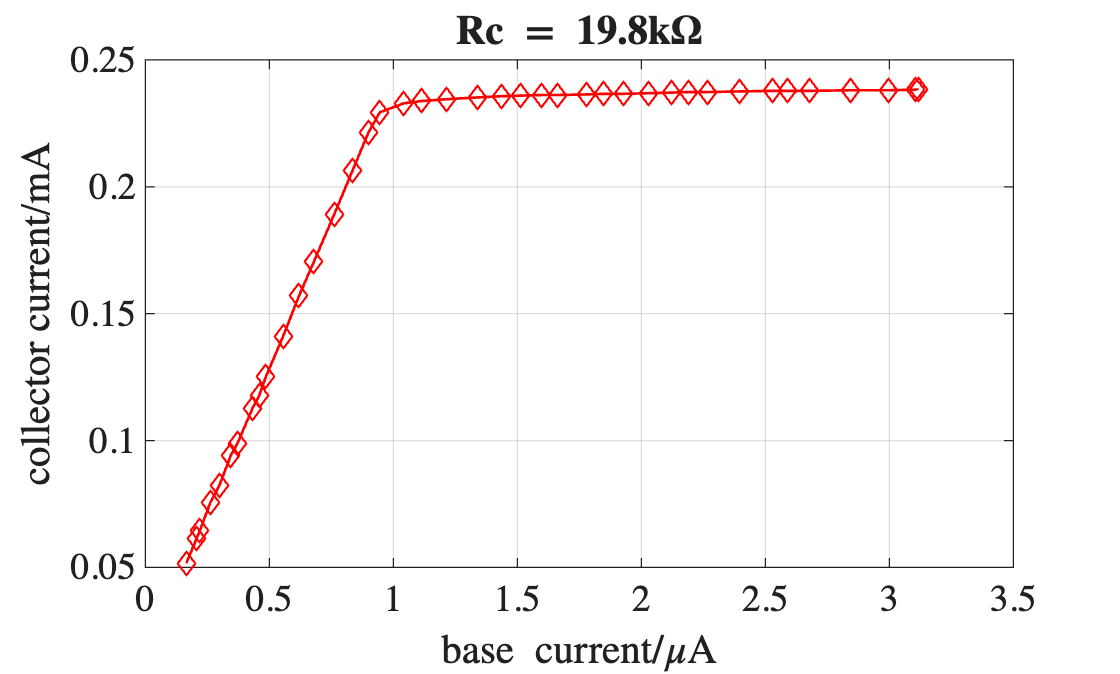

ib10k = ib; ic10k = ic; beta(3) = p(1)*1e3; % save the former results
Rc = Rc+9940; % the old 10k + another 10k in series
data = [ ...   
803	120	156
762	120	165
748	120	168
702	120	177
673	120	185
623	120	195
602	120	201
544	119	213
522	119	219
490	120	226
423	119	240
355	119	254
298	119	267
218	119	285
145	119	301
81	119	315
47	119	325
32	119	346
28	119	362
25	119	384
22	119	411
20	119	432
19	119	449
18	119	467
18	119	481
17	118	506
16	118	521
16	118	538
15	118	560
14	119	581
13	119	596
13	119	613
12	118	640
11	119	670
11	119	683
11	119	703
10	119	739
10	119	772
9	119	796
9	119	798
9	120	799
] * vref/1023; % volts
vce = data(:,1); % collector-emitter voltage
vbe = data(:,2); % base-emitter voltage
vin = data(:,3);
ib = (vin-vbe)/Rb * 1e6; % base current in uA
ic = (vref-vce)/Rc * 1000; % collector current in mA
plot(ib, ic,'d-')
grid; xlabel('base current/\muA'); 
ylabel('collector current/mA')
title(sprintf('Rc = %.1fk\\Omega', Rc/1000)); % why \\?

The asymptote appears consistent with: 

vref / Rc * 1000 % mA

ans = 0.2404

max(ic)

ans = 0.2383

indx = ib > .1 & ic < .95 * max(ic);
p = polyfit(ib(indx), ic(indx), 1); % help polyfit for more info
fprintf('beta = %.1f\n', p(1)*1e3)

beta = 230.3


Let's superimpose these plots: 

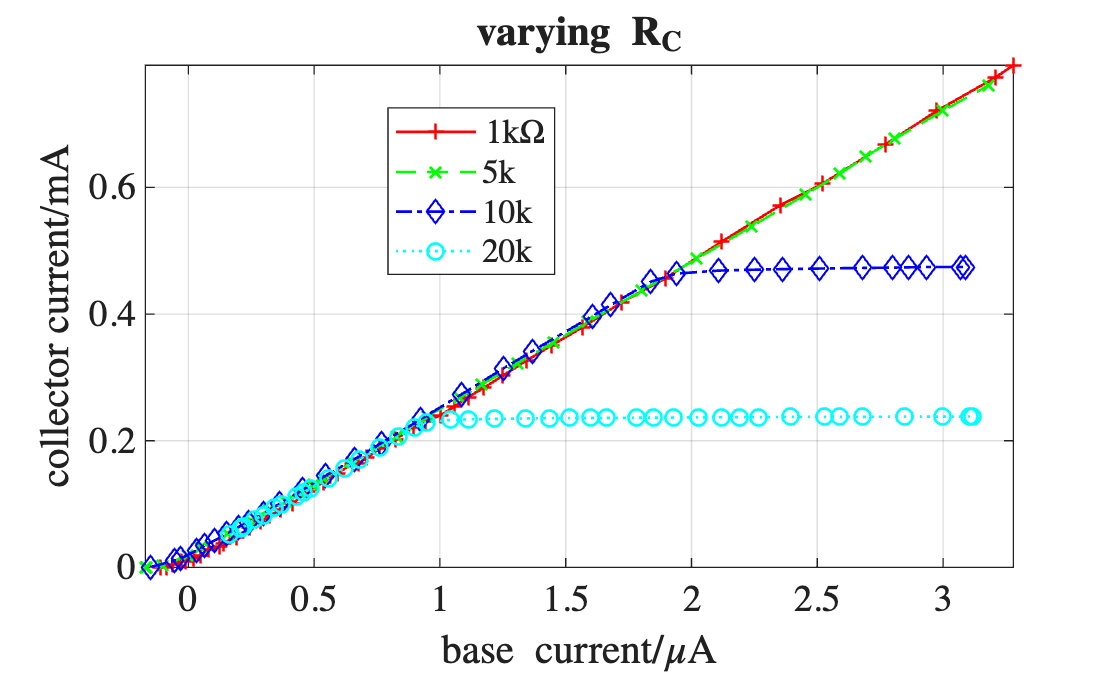

ib20k = ib; ic20k = ic; beta(4) = p(1)*1e3; % for consistency
plot(ib1k,ic1k,'r+-',ib5k,ic5k,'gx--',ib10k,ic10k,'bd-.',ib20k,ic20k,'co:'); 
xlabel('base current/\muA'); ylabel('collector current/mA')
legend('1k\Omega','5k','10k','20k','location','best');
title('varying R_C'); axis tight; grid;

    Figure 8. Superposition of Figs. 5-7, all values of Rc show similar slope (beta) before saturation. 

The value of $\beta$ for this transistor was:

fprintf('beta = %.0f ± %.0f\n', mean(beta), std(beta))

beta = 236 ± 4


## Discussion

If your results look radically different, then troubleshoot, e.g., `plot(data)` might reveal a misconnected AIN. Did you fail to update Rc's value when computing ic? MATLAB facilitates asking questions of your data, e.g., what is `max(data)` and `min(data)`, but your task is to answer whether those results are reasonable or indicative of a bug. 

These curves aren't i-v curves, but ic vs ib curves. This makes sense since transistors have 3 terminals, and hence 2 circuits (with a common emitter), and BJTs are current-controlled-current devices (contrasted to FETs, where (typically) gate-source voltage controls drain-source current). At the bottom left of Figs. 5-8, the transistor is in **cut-off**, with both currents ~0. Next the BJT enters the **active region** characterized by $i_C = \beta i_B$, with linear, constant slope = $\beta$, until the BJT becomes **saturated**, as happened with Rc = 10k at ic ~ .45mA. In the saturated regime, ic is limited by the rest of the circuit (`vref/Rc`) and not the transistor's internal characteristics. 

    Figure 9. Three states of a BJT (Fig. 1). 

I encourage you to measure a second NPN BJT, I wouldn't be surprised if its $\beta$ were significantly different (I've measured between $\approx$ 175-260). 

What other observations or lessons did you learn? 

Automated data collection beats moving voltmeter leads around and manually copying its display to paper and spreadsheets. Arduino measured and printed ~440 voltages for this activity in seconds. Soon we'll be measuring at its top rate ~8500 voltages/second but we slowed it down with `delay(200)`. In subsequent labs, we'll continue automating more aspects of data collection and analysis. First the manual copy/paste operation will be eliminated by establishing a serial connection between MATLAB and Arduino. Manually varying the LM317 voltage can be eliminated too with a (3-transistor) circuit we'll build controlled via Arduino's `analogWrite()` function. At that point, this entire lab could be abstracted into a single MATLAB script or function. Just plug a transistor into the breadboard and run a simple function `measureBeta` that you could write.

#### The Digital Abstraction

Digital circuits use the transistor's cut-off and saturated states to represent the Boolean states of true and false, 1 and 0, or visa-versa. But to transition from either of these states to the other, a transistor must pass through its active region. In other words, a transistor can't go from 0 to 1 without momentarily passing through 0.5 (and 0.6, 0.7321, etc. -- except those "analog values" don't exist in a Boolean world!). So **the voltages and currents in computers and digital circuits are actually continuous and analog**!! What then makes "digital" circuits digital?  I found the answer really surprising .... see if you can find a good explanation. Hint: it has to do with *time*. 

## References

[1] [https://web.mit.edu/6.101/www/reference/2N2222A.pdf](https://web.mit.edu/6.101/www/reference/2N2222A.pdf) 